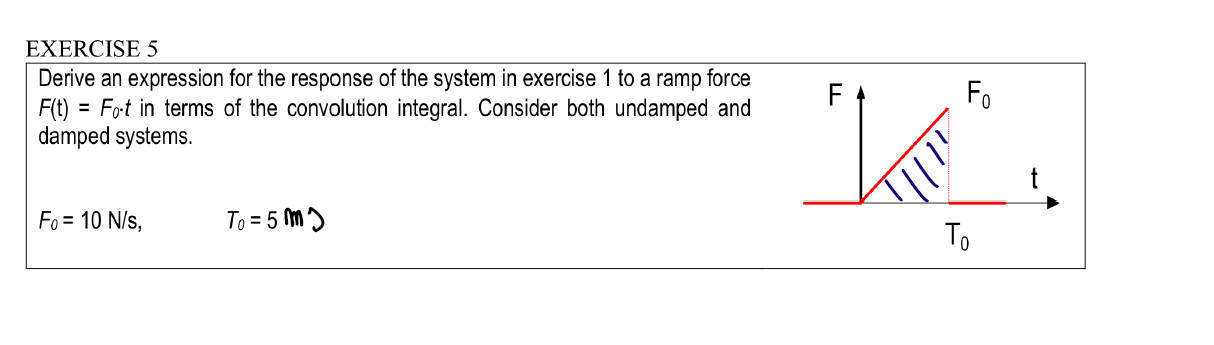

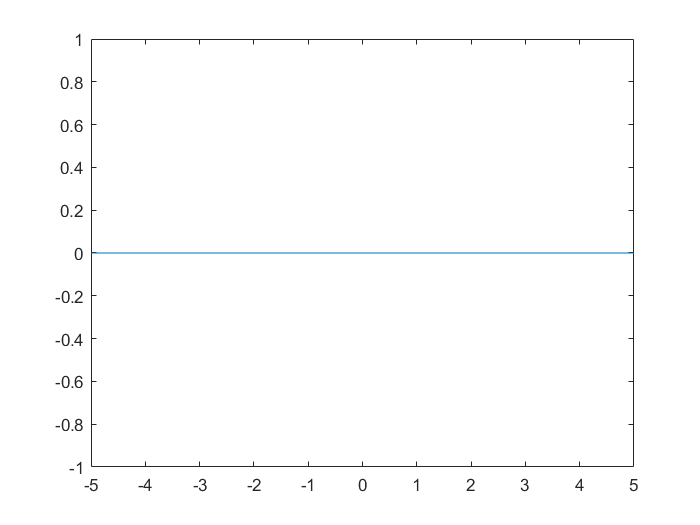

clear
syms F0 T0 F(t) tau h(t) H(s) m k c
T0=5/1000;
F0=10;
m=2;
k = 100;
c=2;
H=1/(m*s^2+c*s+k);

F(t)=piecewise(t<=0,0,0<t<=T0,F0*t,t>T0,0);
fplot(F)


h(t)=ilaplace(H)

$$h(t) = \frac{\sqrt{199}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{199}\,t}{2}\right)}{199}$$

x(t)=int(h(t-tau)*F(t),tau,[0 20*T0]);
x=vpa(x,4)

$$x(t) = \left\{ \begin{array}{cl} 0.0 & \text{ if }t\leq 0\\ 0.007089\,t\,{\mathrm{e}}^{0.05-0.5\,t}\,\left(14.11\,\cos\left(7.053\,t-0.7053\right)+\sin\left(7.053\,t-0.7053\right)\right)-0.007089\,t\,{\mathrm{e}}^{-0.5\,t}\,\left(14.11\,\cos\left(7.053\,t\right)+\sin\left(7.053\,t\right)\right) & \text{ if }t\in \left(0.0,0.005\right]\\ 0.0 & \text{ if }0.005<t \end{array}\right.$$

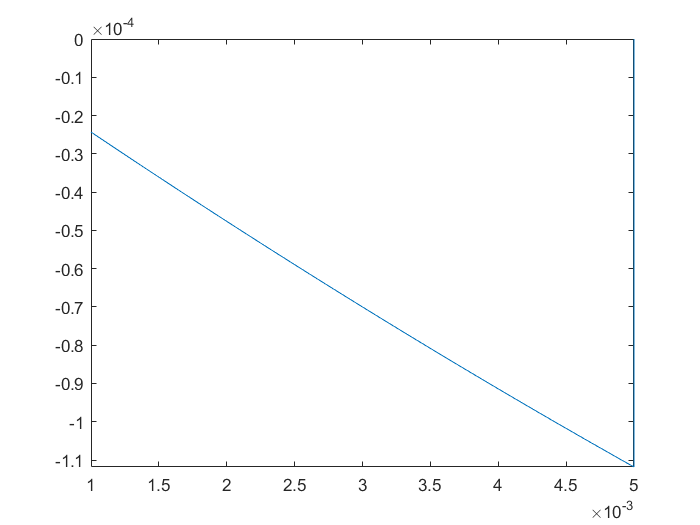

fplot(x,[0.001,0.005])